clear; clc;
% DERIVING GRADIENTS
syms x_1 x_2
u = (1/2)*(x_1^2 + x_2^2 - 25);
f_sym = exp(u^2) + sin(4*x_1 - 3*x_2)^4 + 0.5*(2*x_1 + x_2 - 10)^2;
% f_sym = (1-x_1)^2 + 100*(x_2-x_1^2)^2;
f = matlabFunction(f_sym); f = @(x) f(x(1), x(2));

grad = [diff(f_sym, x_1); diff(f_sym, x_2)];
f_grad = matlabFunction(grad); f_grad = @(x) f_grad(x(1), x(2));

grad = [diff(grad(1), x_1) diff(grad(1), x_2);
        diff(grad(2), x_1) diff(grad(2), x_2)];
f_grad2 = matlabFunction(grad); f_grad2 = @(x) f_grad2(x(1), x(2));

% SETUP
% x0 = [4; -1]; x = x0;
x0 = [2; 3]; x = x0;
dx = Inf;
fCalls = [0 0 0];
t0 = 0.1;
i = 0;
tic
filename = 'hw3p3_3BFGS.png';
while dx > 1e-8
    i = i+1;
    % FINDING DIRECTION
    if i == 1; dir0 = []; else; dir0 = dir(i-1); end
%     dir(i) = steepestDescent(x, f_grad); % Steepest Descent
%     dir(i) = fletchReev(x, f_grad, dir0); % Fletcher-Reeves
%     dir(i) = polakRibiere(x, f_grad, dir0); % Polak Ribiere
    dir(i) = BFGS(x, f_grad, dir0); % Broyden-Fletcher-Goldfarb-Shanno
    s = dir(i).s;
    fCalls = fCalls + dir(i).fCalls;
    
    % LINE SEARCHING
    lin(i) = lineSearch(x, s, f, t0, 4, 2);
    fCalls = fCalls + lin(i).fCalls;
    
    % MINIMIZING
    mini(i) = grMin([lin(i).pts(:).x], f);
%     mini(i) = quadMin([lin(i).pts(:).x], s, f, f_grad, f_grad2);
    fCalls = fCalls + mini(i).fCalls;
    
    % ALIGNING NEW MINIMUM
    %     if norm(x - mini(i).xmin) < 1e-8; warning('WARNING: dx = 0'); break; end
    dx = norm(x - mini(i).xmin);
    x = mini(i).xmin;
%     grad = f_grad(x);
%     fCalls(2) = fCalls(2) + 1;
    if i == 1000; break; end
end
fCalls(2) = fCalls(2) + 1;
if norm(f_grad(x)) > 1e-4
    warning('WARNING: May not have found minimum');
end

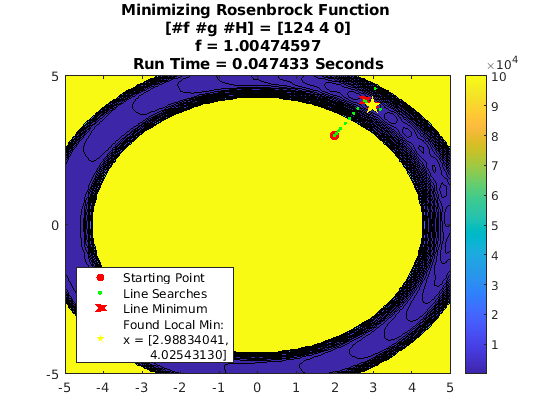

time = toc;

% PLOTTING
x1_space = -5:0.1:5;
x2_space = -5:0.1:5;
z_space = zeros(length(x1_space));
for i = 1:length(x1_space)
    for j = 1:length(x1_space)
        z_space(j, i) = f([x1_space(i), x2_space(j)]); 
    end
end

% Contour
contourf(x1_space, x2_space, z_space, [logspace(0, 5, 22)], ...
    'HandleVisibility',"off")
hold on

% Start Point
scatter(x0(1), x0(2), 50, 'ro', 'filled', 'DisplayName', 'Starting Point')

% Creating Initial Plots and Legend Entries
x = lin(1).allPts;
scatter(x(1, :), x(2, :), 20, 'g.', 'DisplayName', 'Line Searches')
xmin = mini(1).xmin;
scatter(xmin(1), xmin(2), 30, 'rx', 'DisplayName', 'Line Minimum', 'linewidth', 5)

% Rest of Line Searches
l = length(lin); if l > 100; l = 100; end
for i = 2:l
    % Line Searches
    x = lin(i).allPts;
    scatter(x(1, :), x(2, :), 20, 'g.', 'HandleVisibility', 'off')
    
    % Minimums
    xmin = mini(i).xmin;
    scatter(xmin(1), xmin(2), 30, 'rx', 'HandleVisibility', 'off', 'linewidth', 5)
end

% Final Point
scatter(xmin(1), xmin(2), 200, 'yp', 'filled', 'linewidth', 1, ...
    'DisplayName', sprintf('Found Local Min:\nx = [%0.8f,\n       %0.8f]', xmin(1), xmin(2)))
hold off
xticks(-5:5)
xlim([-5 5])
ylim([-5 5])
colorbar
legend('Location', 'southwest')
title(sprintf('Minimizing Rosenbrock Function \n[#f #g #H] = [%i %i %i]\nf = %0.8f\nRun Time = %0.6f Seconds', fCalls(1), fCalls(2), fCalls(3), f(xmin), time))
exportgraphics(gcf, filename, 'Resolution', 200)

function out = levenMarq_(x, f, g, H, prev)
    % SETUP
    if isempty(prev)
        lam = 1e4; gam = 2;
        Jlast = Inf;
        J = f(x)
    end
%{
    % SETUP
    lam = 1e4; gam = 2;
    if isempty(prev); Jlast = Inf; else; Jlast = prev.J; end
    
    % FINDING NEW POINTS
    J = f(x);
    dJ = g(x);
    d2J = H(x);
    fCall = [1 1 1];
    lamMin = min(eig(d2J));
    if lamMin > 0 && norm(dJ) < 1e-4
        out.J = J;
        out.x = x;
        return
    end
    
    % CREATING TEST POINT
    xtest = (d2J + lam*eye(length(x))) \ -dJ;
    Jtest = f(xtest); fCall(1) = fCall(1)+1;
    
    % IF NEW POINT IS NOT BETTER
    while Jtest > Jlast
        % UPDATING
        lam = gam*lam;
        
        % CREATING TEST POINT
        xtest = (d2J + lam*eye(length(x))) \ -dJ;
        Jtest = f(xtest); fCall(1) = fCall(1)+1;
    end
    
    % ACCEPTING STEP
    x = xtest;
    J = f(x);
    dJ = g(x);
    d2J = H(x);
    fCall = fCall + [1 1 1];
    lamMin = min(eig(d2J));
    if lamMin > 0 && norm(dJ) < 1e-4
        out.J = J;
        out.x = x;
        return
    end
%}
end

function out = BFGS(x, g, prev)
    if isempty(prev)
        gk1 = g(x);
        Qk1 = eye(length(x));
    else
        % EVALUTING NEW TERMS
        gk1 = g(x);
        Qk = prev.Q;
        
        % CREATING CONSTANTS
        p = x - prev.x;
        y = gk1 - prev.g;
        sig = p.' * y;
        tau = y.' * Qk * y;
        A = Qk * y * p.';
        
        % COMPUTING UPDATE
        dQ = ((sig + tau)/sig^2)*(p * p.') - (1/sig)*(A + A.');
        Qk1 = Qk + dQ; % Creating approximated Hessian
    end
    
    out.s = -Qk1*gk1; out.s = out.s/norm(out.s);
    out.x = x;
    out.fCalls = [0 1 0];
    out.g = gk1;
    out.Q = Qk1;
end

function out = polakRibiere(x, g, prev)
    if isempty(prev)
        g1 = -g(x);
        s = g1;
    else
        g0 = prev.g;
        s = prev.s;
        g1 = -g(x);
        y1 = g1 - g0;
        beta = (g1.' * y1) / norm(g0)^2;
        s = g1 + beta*s;
    end
    
    out.s = s/norm(s);
    out.fCalls = [0 1 0];
    out.g = g1;
end

function out = fletchReev(x, g, prev)
    if isempty(prev)
        g1 = -g(x);
        s = g1;
    else
        g0 = prev.g;
        s = prev.s;
        g1 = -g(x);
        beta = norm(g1)^2 / norm(g0)^2;
        s = g1 + beta*s;
    end
    
    out.s = s/norm(s);
    out.fCalls = [0 1 0];
    out.g = g1;
end

function out = steepestDescent(x, g)
    s = zeros(length(x), 1);
    s = -g(x);
    out.s = s/norm(s);
    out.fCalls = [0 1 0];
end

function out = lineSearch(x0, s, f, t0, steps, stepMod)
    % SETUP
    fCalls = 0;
    z = f(x0); fCalls = fCalls+1;
    x = zeros(length(x0), 1); 
    x(:, end) = x0;           % Enforcing column vectors
    t = t0;
    iter = 1; iterTot = 1;
    
    % ITERATING UNTIL MINIMUM BRACKETED
    while length(z) < 3 || z(end) < z(end-1)
        % INCREASING STEP SIZE IF NOT BRACKETING
        if iter == steps
            t = stepMod*t;
            iter = 0;
        end
        
        % STEPPING AND EVALUATING
        x = cat(2, x, x(:, end) + t*s);
        z(end+1) = f(x(:, end)); fCalls = fCalls+1;
        iter = iter+1;
        iterTot = iterTot+1;
        
        if iter == 31
            pts = [];
            warning("lineSearch() ran out of iterations")
            return
        end
    end
    
    % OUTPUTTING POINTS
    pts = struct('x', x(:, end-2), 'z', z(end-2));
    pts(end+1) = struct('x', x(:, end-1), 'z', z(end-1));
    pts(end+1) = struct('x', x(:, end), 'z', z(end));
    out.pts = pts;
    out.iters = iterTot;
    out.allPts = x;
    out.fCalls = [fCalls 0 0];
end
function out = quadMin(x, s, f, f_grad, f_grad2)
    % SETUP
    alpha = inf;
    iters = 0;
    fCalls = 3;
    dfCalls = 0;
    d2fCalls = 0;
    
    % ITERATING
    for i = 1:3; z(i) = f(x(:, i)); end
    while abs(alpha) > 1e-8
        [~, idx] = min(z);
        
        % FINDING STEP SIZE
        alpha = -(f_grad(x(:, idx)).'*s) / (s.' * f_grad2(x(:, idx)) * s);
        dfCalls = dfCalls+1;
        d2fCalls = d2fCalls+1;
        
        % STEPPING
        x = cat(2, x, x(:, idx) + alpha*s);
        z(end+1) = f(x(:, end));
        fCalls = dfCalls+1;
        iters = iters+1;
        if iters > 51; break; end
    end
    
    % OUTPUTTING
    [~, idx] = min(z);
    out.xmin = x(:, idx);
    out.zmin = z(idx);
    out.iters = iters;
    out.fCalls = [fCalls, dfCalls, d2fCalls];
end

function out = grMin(x0, f)
    % SETUP
    alpha = (3 - sqrt(5))/2;   % Step Size
    
    xL = x0(:, 1);             % Creating Points
    xR = x0(:, 3);             % |
    x1 = xL + alpha*(xR - xL); % |
    x2 = xR - alpha*(xR - xL); % #
    
    fL = f(xL);                % Evaluating at Points
    f1 = f(x1);                % |
    f2 = f(x2);                % |
    fR = f(xR);                % #
    
    X = [xL x1 x2 xR];         % Creating Test Matrix
    dx = inf;                  % Initializing Error
    iters = 0;
    fCalls = 4;
    
    % ITERATING
    allX = X;
    while abs(dx) > 1e-8
        if f1 > f2
            % MOVING BOUNDS
            xL = x1; fL = f1;
            x1 = x2; f1 = f2;
            
            % RE-EVALUTING POINT
            x2 = xR - alpha*(xR - xL);
            allX = cat(2, x2, allX); 
            f2 = f(x2);
        else
            % MOVING BOUINDS
            xR = x2; fR = f2;
            x2 = x1; f2 = f1;
            
            % RE-EVALUTING POINT
            x1 = xL + alpha*(xR - xL);
            allX = cat(2, x1, allX);
            f1 = f(x1);
        end

        fCalls = fCalls+1;
        Xnew = [xL, x1, x2, xR];
        dx = norm(Xnew, 'fro') - norm(X, 'fro');
        X = Xnew;
        iters = iters+1;
        if iters > 51; break; end
    end
    
    % FINDING RESULTS
    [out.zmin, idx] = min([fL, f1, f2, fR]);
    out.xmin = X(:, idx);
    out.allPts = allX;
    out.iters = iters;
    out.fCalls = [fCalls 0 0];
end